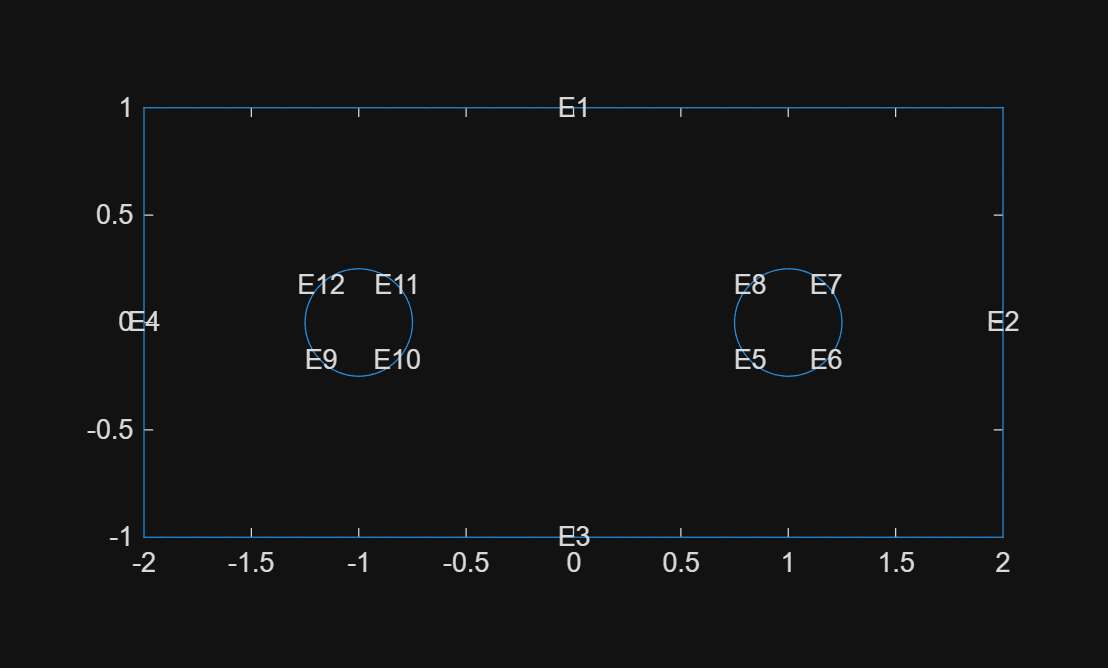

model = createpde;
R1 = [3,4,-2,2,2,-2,1,1,-1,-1]';

C2 = [1, 1, .0,0.25]';
C1 = [1,-1,-.0,0.25]';
% C2 = [1, 0,  0,1.00]';
% C1 = [1, 0,  0,0.25]';

C1 = [C1' zeros(1,6)]';
C2 = [C2' zeros(1,6)]';

gm = [R1,C2,C1];
sf = 'R1-C2-C1';
% sf = 'C2+C1';
ns = char('R1','C2','C1');
ns = ns';

g = decsg(gm,sf,ns);
geometryFromEdges(model,g);
pdegplot(model,EdgeLabels="on")

Nb = 100;
hps  = 2*pi*.25/Nb;
% hps  = .01;
Nhps = {5,hps,6,hps,7,hps,8,hps,9,hps,10,hps,11,hps,12,hps};
% Nhps = {5,hps,6,hps,7,hps,8,hps};
M = generateMesh(model,hmax=.01,Hedge=Nhps,GeometricOrder="linear")

M =   FEMesh with properties:

             Nodes: [2×86036 double]
          Elements: [3×170618 double]
    MaxElementSize: 0.0100
    MinElementSize: 0.0050
     MeshGradation: 1.5000
    GeometricOrder: 'linear'

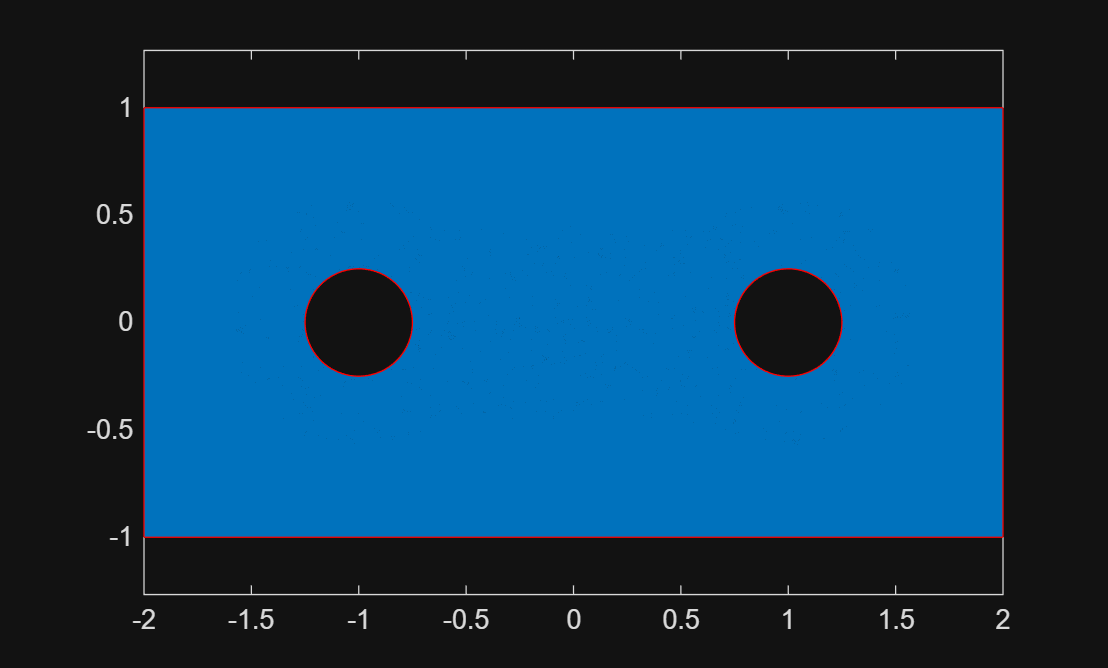

pdemesh(M);

drawnow;

TR = triangulation(M.Elements',M.Nodes');
DTR  = delaunayTriangulation(TR.Points);
FB = freeBoundary(DTR);
Rt = TR.Points;


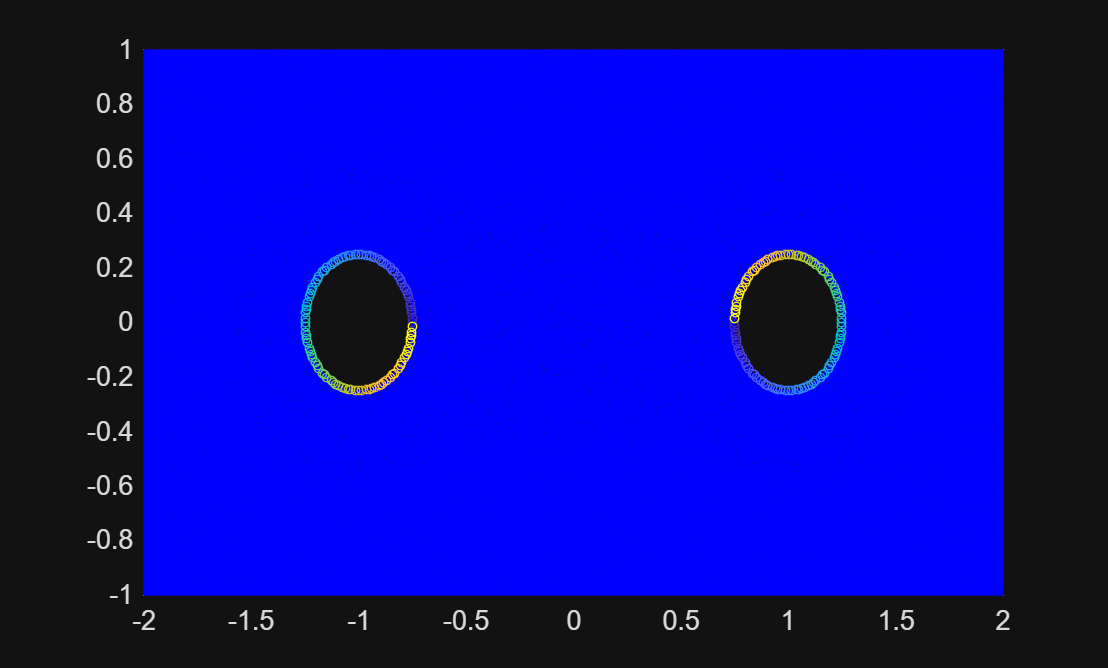


I = 1:size(Rt,1);
I(FB) = [];
perm = [I unique(FB)'];

PortI = linspace(0,2*pi*(1-1/Nb),Nb)';
X1 =  C1(4)*cos(PortI+00)+C1(2);
X2 =  C2(4)*cos(PortI+pi)+C2(2);
Y1 =  C1(4)*sin(PortI+00)+C1(3);
Y2 =  C2(4)*sin(PortI+pi)+C2(3);

NM = [];

NM(:,1) = nearestNeighbor(TR,X1,Y1);
NM(:,2) = nearestNeighbor(TR,X2,Y2);

triplot(TR);
hold on;
scatter(Rt(NM(:,1),1),Rt(NM(:,1),2),10,1:size(PortI,1))
scatter(Rt(NM(:,2),1),Rt(NM(:,2),2),10,1:size(PortI,1))

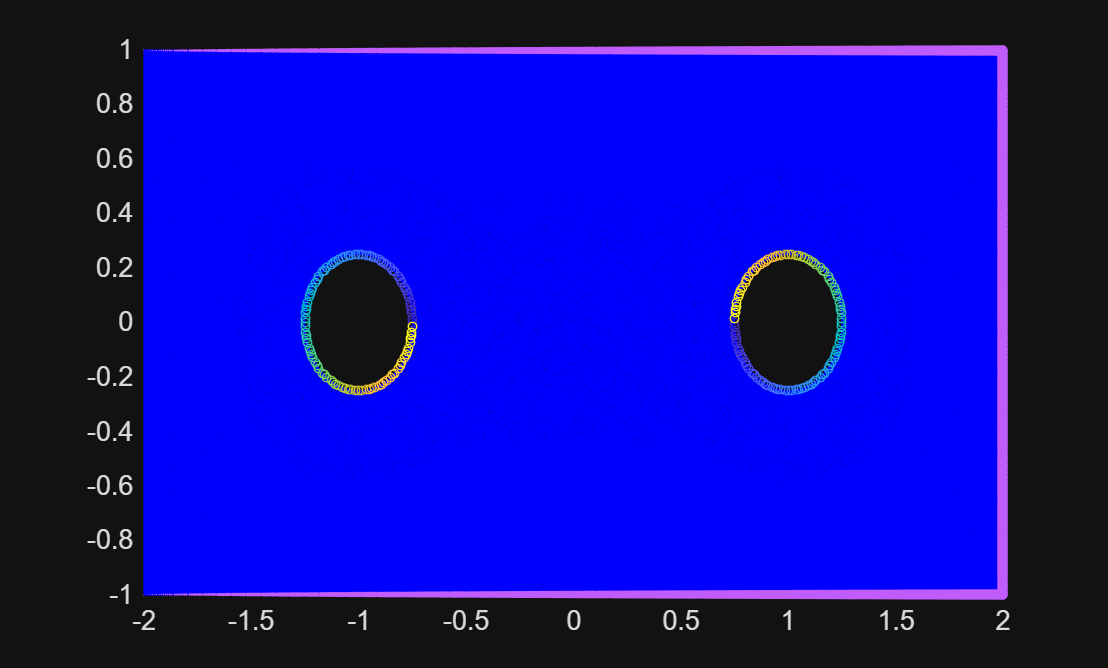

D = TR.ConnectivityList;
A = Rt(D(:,1),1).*(Rt(D(:,2),2)-Rt(D(:,3),2))+ ...
    Rt(D(:,2),1).*(Rt(D(:,3),2)-Rt(D(:,1),2))+ ...
    Rt(D(:,3),1).*(Rt(D(:,1),2)-Rt(D(:,2),2));

E = edges(TR);

El = vecnorm([Rt(E(:,1),1)-Rt(E(:,2),1)  Rt(E(:,1),2)-Rt(E(:,2),2)],2,2);

EM = sparse(E(:,1),E(:,2),El,size(Rt,1),size(Rt,1));

EM = EM + EM';

rho = zeros(1,size(EM,1));
BV = unique(FB);
rho(BV) = (Rt(BV,1)+2)*4;

scatter(Rt(rho>0,1),Rt(rho>0,2),rho(rho>0),'filled')

EM = EM(perm,perm);
rho = rho(perm);
Rt = Rt(perm,:);
I = I;

NM  = changem(NM,1:numel(perm),perm);
% D  = perm( D); 
D  = changem(D,1:numel(perm),perm);

size(EM)

ans =        86036       86036


EMT1 = EM(NM(:,1),:);
EM(NM(:,2),:) = EM(NM(:,2),:)+EMT1 ;
EM(:,NM(:,2)) = EM(:,NM(:,2))+EMT1';
EM(NM(:,1),:) = [];
EM(:,NM(:,1)) = [];
size(EM)

ans =        85936       85936



rhoT1 = rho(NM(:,1));
rho(NM(:,2)) = rhoT1;
rho(NM(:,1)) = [];

Rt(NM(:,1),:) = [];

I(NM(:,1)) = [];

NumNodes = size(EM,2)

NumNodes = 85936

NumNodesI = size(I,2)

NumNodesI = 84736


CSF = zeros(1, size(perm,2));
CSF(NM(:,1)) = 1;       % mark where increases happen
CSF = (1:size(perm,2))-cumsum(CSF);    % make it monotonic

% D = changem(D,NM(:,1),NM(:,2));
D = changem(D,NM(:,2),NM(:,1));
D = changem(D,CSF,1:numel(CSF));

% D = CSF(D);



AdjMat = sparse(NumNodes,NumNodes,'double');
b = 0.*rho;
M = 0*AdjMat;

for kk = 1:size(D,1)

    i = D(kk,1); 
    j = D(kk,2);
    k = D(kk,3);

    li = EM(j,k);
    lj = EM(i,k);
    lk = EM(i,j);

  % AdjMat(i,j) = AdjMat(i,j)+A(kk).^2/(li*lj).^2;
  % AdjMat(j,k) = AdjMat(j,k)+A(kk).^2/(lj*lk).^2;
  % AdjMat(k,i) = AdjMat(k,i)+A(kk).^2/(lk*lj).^2;


  AdjMat(i,j) = AdjMat(i,j)+A(kk).^1/(lk).^2;
  AdjMat(j,k) = AdjMat(j,k)+A(kk).^1/(li).^2;
  AdjMat(k,i) = AdjMat(k,i)+A(kk).^1/(lj).^2;

  % AdjMat(i,j) = AdjMat(i,j)+1;
  % AdjMat(j,k) = AdjMat(j,k)+1;
  % AdjMat(k,i) = AdjMat(k,i)+1;

  % AdjMat(i,j) = AdjMat(i,j)+A(kk).^-1/(lk).^-2;
  % AdjMat(j,k) = AdjMat(j,k)+A(kk).^-1/(li).^-2;
  % AdjMat(k,i) = AdjMat(k,i)+A(kk).^-1/(lj).^-2;

  M(i,i) = M(i,i) + A(kk);%.*2;
  M(j,j) = M(j,j) + A(kk);%.*2;
  M(k,k) = M(k,k) + A(kk);%.*2;
  % M(i,j) = M(i,j) + A(kk);
  % M(j,i) = M(j,i) + A(kk);
  % M(k,j) = M(k,j) + A(kk);
  % M(j,k) = M(j,k) + A(kk);
  % M(i,k) = M(i,k) + A(kk);
  % M(k,i) = M(k,i) + A(kk);

end

% M(D(:,1),D(:,1)) = M(D(:,1),D(:,1))  
% M(D(:,1),D(:,1)) = M(D(:,2),D(:,2)) 
% M(D(:,1),D(:,1)) = M(D(:,3),D(:,3)) 
% M(D(:,1),D(:,2)) = M(D(:,1),D(:,2)) 
% M(D(:,2),D(:,3)) = M(D(:,2),D(:,3)) 
% M(D(:,1),D(:,3)) = M(D(:,1),D(:,3))  



% AD = A*[1 1 1];

% M = M*0;

% M(,D(:)) = M(D(:),D(:)) + AD(:);

M = M + M';

AdjMat = AdjMat + AdjMat';


% AdjMat  = AdjMat.^-1;

AdjMat = AdjMat - diag(sum(AdjMat,2));

AdjMatBC = AdjMat(1:NumNodesI,(NumNodesI+1):end);
AdjMat = AdjMat(1:NumNodesI,1:NumNodesI);


rho = M*rho';

% M = M(1:NumNodesI,1:NumNodesI);

rhoBC = rho((NumNodesI+1):end);
rho = rho(1:NumNodesI);
[AdjMatR] = chol(-AdjMat);  

b = rho-AdjMatBC*rhoBC;
% psi = AdjMatR\(AdjMatR'\b);
psi = b;
alpha = .1;

for i=1:10000

    psi = psi-alpha*(b-AdjMat*psi);

end


F = scatteredInterpolant(Rt(1:NumNodesI,1),Rt(1:NumNodesI,2),psi,'linear','none');
[xqp,yqp] = meshgrid(-1.9:.005:1.9,-.9:.005:.9);

% imshow(mat2gray(F(xq,yq)),Colormap=parula,XData=[0 1],YData=[0 1])
hold off

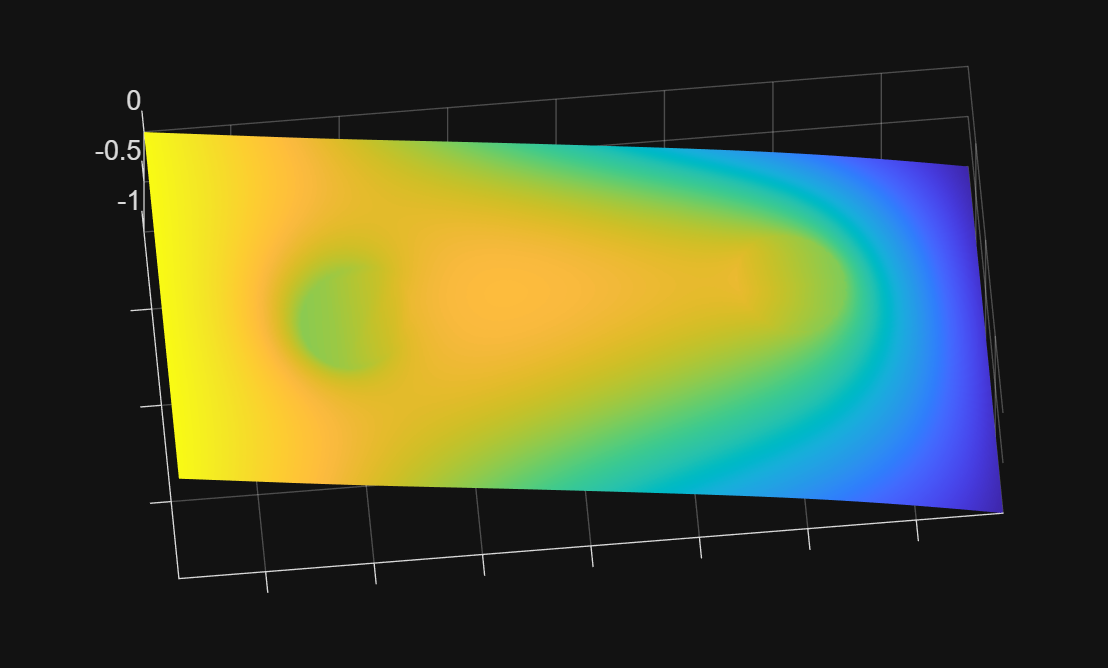

surf(xqp,yqp,-mat2gray(F(xqp,yqp)),EdgeColor="none")
hold on
% plot(xt(FB),yt(FB),'*w')
% triplot(DT,'cyan');
axis equal;
xticklabels([])
yticklabels([])

drawnow;

[xq,yq] = meshgrid(-1.9:.05:1.9,-.9:.05:.9);
[Fx,Fy] = gradient(F(xqp,yqp));
Fm = sqrt(Fx.^2+Fy.^2);
Fg = scatteredInterpolant(xqp(:),yqp(:),Fm(:),'natural');
[Fx,Fy] = gradient(F(xq,yq));

function mapout = changem(mapout, newcode, oldcode)
   assert(numel(newcode) == numel(oldcode), 'newcode and oldecode must have the same number of elements');
   [toreplace, bywhat] = ismember(mapout, oldcode);
   mapout(toreplace) = newcode(bywhat(toreplace));
end